# SafianGRIDtx Created by Mahmoud Safian on 2022-11-25

warning off; clc; clear;

## Syntax:

	runStateEstimator(DATA, METHOD)

	runStateEstimator(DATA, METHOD, START)

	runStateEstimator(DATA, METHOD, START, ATTACH)

	runStateEstimator(DATA, METHOD, START, ATTACH, SET)

	runStateEstimator(DATA, METHOD, START, ATTACH, SET, VARIANCE)

	runStateEstimator(DATA, METHOD, START, ATTACH, SET, VARIANCE, DISPLAY, EXPORT)

## Examples:

	runStateEstimator('ieee14_20', 'nonlinear', 'warm', 'maxIter', 100, 'main');

	runStateEstimator('data\ieee14_20', 'pmu', 'pmuDevice', 'pmuRandom', [10^-12 10^-10], 'main' ,'export');

	runStateEstimator('ieee14_20', 'dc', 'main');

	runStateEstimator('ieee14_20', 'dc', 'legDevice', [10 0 4 0], 'estimate');

	runStateEstimator('ieee14_20', 'dc', 'legUnique', 10^-4, 'estimate');

## Description:

	- runStateEstimator(DATA, METHOD) computes state estimation problem using WLS

	- runStateEstimator(DATA, METHOD, START) the Gauss-Newton initial point

	- runStateEstimator(DATA, METHOD, START, ATTACH) the Gauss-Newton maximum number

	  of iterations, as well bad data processing and least absolute value

	  state estimation

	- runStateEstimator(DATA, METHOD, START, ATTACH, SET) defines measurement set

	- runStateEstimator(DATA, METHOD, START, ATTACH, SET, VARIANCE) defines measurement

	  variances

	- runStateEstimator(DATA, METHOD, START, ATTACH, SET, VARIANCE, DISPLAY, EXPORT)

	  allows to show results and export models

## Input Arguments:

	- **DATA**: the first input argument in the runStateEstimator function must contain a

	  name of the mat-file that contains power system and measurement data

	- **METHOD**:

		- 'nonlinear' / 'ac': non-linear state estimation based on the WLS

                - 'pmu': WLS linear PMU state estimation;

		- 'dc': WLS DC state estimation;

	- **START**

		- 'warm': the Gauss-Newton initial point defined as the one applied

		   in the AC power flow

		- 'exact': the Gauss-Newton initial point defined from the exact

		   values, if those exist

		- 'flat', [X Y]: unique the Gauss-Newton initial point for voltage

		   angles (X) in degree and magnitude (Y) in per-unit

		   default setting: [0 1]

		- 'random', [X Y Z V]: the Gauss-Newton initial point defined using

		   random perturbation between minimum (X) and maximum values (Y)

		   of voltage angles in degrees, and minimum (Z) and maximum (V)

		   values of voltage magnitudes in per-units

		   default setting: [-0.5 0.5 0.95 1.05]

	- **ATTACH**

		- 'bad': bad data processing

		- 'lav': least absolute value state estimation

                - 'observe': observability analysis (only the DC state estimation)

		- 'maxIter', X: maximum number of the Gauss-Newton iterations(X)

	- **SET**

		- 'pmuOptimal': optimal PMU location to make the entire system

		   completely observable only by phasor measurements

		- 'pmuRedundancy', X: randomize phasor measurements according to

		   redundancy X;

		   default setting: maximum value of legacy redundancy

		- 'pmuDevice', X: enables phasor measurements according to number

		   of measurement devices X placed on buses

		   default setting: all PMUs are active

		- 'legRedundancy', X: randomize legacy measurements according to

		   redundancy X

		   default setting maximum value of phasor redundancy

		- 'legDevice', [X Y Z V]: enables legacy measurements according to

		   device subsets [(Pij,Qij),(Iij),(Pi,Qi),(Vi)]

		   default setting: all legacy devices are active

	- **VARIANCE**

		- 'pmuUnique', X: applied unique variance X over all phasor

		   measurements

		   default setting: 10^-12;

		- 'pmuRandom', [X Y]: randomized variances within limits X and Y

		   applied over all phasor measurements

		   default setting: [10^-12 10^-10];

		- 'pmuType', [X Y Z V]: defining variances over the subset of

		   measurements from PMUs (Iij, Dij, Vi, Ti)

		   default setting: [10^-10 10^-12 10^-10 10^-12];

		- 'legUnique', X: applied unique variance X over all legacy

		   measurements

		   default setting: 10^-8;

		- 'legRandom', [X Y]: randomized variances within limits X and Y

		   applied over all legacy measurements

		   default setting: [10^-9 10^-8];

		- 'legType', [X Y Z V P Q]: defining variances over the subset of

		   legacy measurements (Pij, Qij, Iij, Pi, Qi, Vi)

		   default setting: [10^-6 10^-8 10^-8 10^-6 10^-8 10^-8];

	- **DISPLAY**

		- 'main': bus data display

		- 'flow': power flow data display

		- 'estimate': estimation data display

		- 'error': evaluation data display

	- **EXPORT**

		- 'save': save display data

		- 'export': export the system model without slack bus (for linear

		   state estimation problems, exports in data.extras)

		- 'exportSlack': export the system model with slack bus (for

		   DC state estimation problem, exports in data.extras)

[result, data] = runStateEstimator('data\ieee14_20', 'pmu', 'pmuDevice', 'pmuRandom', [10^-12 10^-10], 'main' ,'export');

 
 
	Method: Linear Weighted Least-Squares State Estimation only with PMUs
	Power System: data\ieee14_20.mat
	Date: 22.01.2023 17:20:25 
 
	Preprocessing time: 0.06397 seconds
	Convergence time: 0.00062 seconds
	Postprocessing time: 0.05923 seconds
 
   _______________________________________________________________________________________________
  |     Bus                Voltage               Injection Power      |       Shunt Element       |
  |                   Vm[pu]  |  Va[deg]        P[MW]  |  Q[MVAr]     |     P[MW]  |  Q[MVAr]     |
  | ------------------------------------------------------------------|---------------------------|
  |     1             1.0600     -0.0001       232.39      -16.55     |      0.00        0.00     |
  |     2             1.0450     -4.9826        18.30       30.86     |      0.00        0.00     |
  |     3             1.0100    -12.7252       -94.20        6.08     |      0.00        0.00     |
  |     4             1.0177    -10.3130       -47

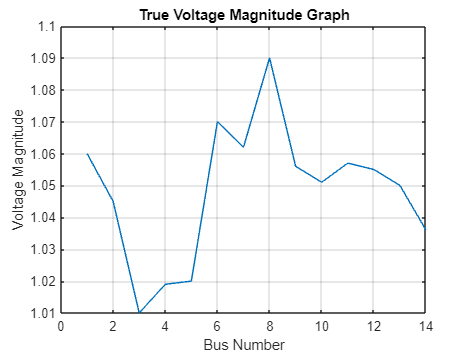

figure(1);
plot(data.system.bus(:, 1), data.system.bus(:,3));
grid on
title("True Voltage Magnitude Graph");
xlabel("Bus Number");
ylabel("Voltage Magnitude");

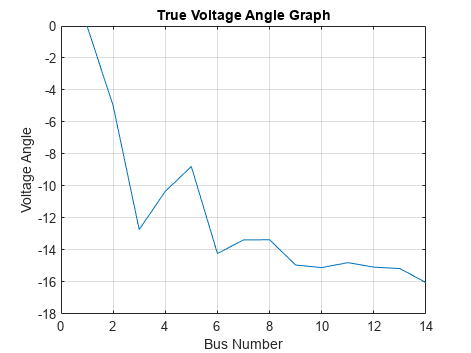

figure(1);
plot(data.system.bus(:, 1), data.system.bus(:,4));
grid on
title("True Voltage Angle Graph");
xlabel("Bus Number");
ylabel("Voltage Angle");

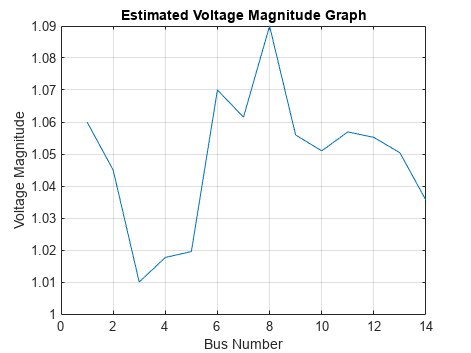

figure(3);
plot(result.bus.Bus, result.bus.Vmag);
grid on
title("Estimated Voltage Magnitude Graph");
xlabel("Bus Number");
ylabel("Voltage Magnitude");

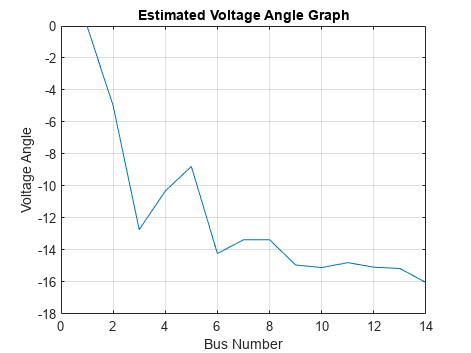

figure(4);
plot(result.bus.Bus, result.bus.Vang);
grid on
title("Estimated Voltage Angle Graph");
xlabel("Bus Number");
ylabel("Voltage Angle");

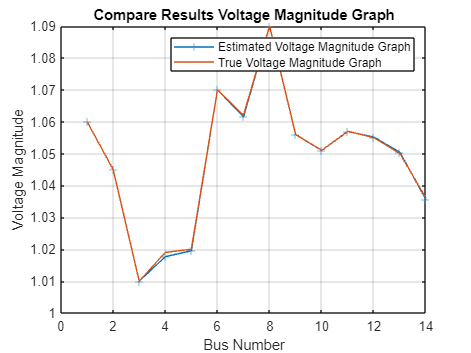

figure(5);
plot(result.bus.Bus, result.bus.Vmag, '+-', data.system.bus(:, 1), data.system.bus(:,3));
grid on
legend("Estimated Voltage Magnitude Graph", "True Voltage Magnitude Graph")
title("Compare Results Voltage Magnitude Graph");
xlabel("Bus Number");
ylabel("Voltage Magnitude");

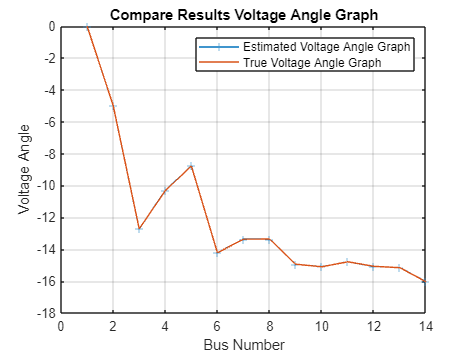

figure(5);
plot(result.bus.Bus, result.bus.Vang, '+-', data.system.bus(:, 1), data.system.bus(:,4));
grid on
legend("Estimated Voltage Angle Graph", "True Voltage Angle Graph")
title("Compare Results Voltage Angle Graph");
xlabel("Bus Number");
ylabel("Voltage Angle");

function [re, data] = runStateEstimator(varargin)
[user, data] = settings_state_estimation(varargin);
[data] = load_power_system(data, user);
[data] = load_measurements(user, data);

if ismember('bad', user.list)
    [user] = check_bad_data(user);
end
[sys] = container(data);
if any(ismember({'nonlinear', 'pmu', 'pmuOptimal'}, user.list))
    [sys] = ybus_ac(sys);
end

[data] = runplay(user, data, sys);
if ismember('nonlinear', user.list)
    [user] = check_start(user);
    [user] = check_maxiter(user);
    
    [bra] = branchDataIndecies(sys);
    [sys] = composFlow(data.legacy.flow, sys, bra);
    [sys] = composCurrent(data.legacy.current, data.pmu.current, sys, bra);
    [sys] = composInjection(data.legacy.injection, sys);
    [sys] = composeVoltages(data.legacy.voltage, data.pmu.voltage, sys);
    [sys, se] = composeMeasurements(sys);
    
    if ismember('bad', user.list)
        [se] = gauss_newton_bad_data(user, sys, se, data);
    elseif ismember('lav', user.list)
        [se] = gauss_newton_lav(user, sys, se, data);
    else
        [se] = gauss_newton(user, sys, se, data);
    end
    
    [se] = processingIndecies(sys, se);
    [sys, se] = evaluationIndecies(data, sys, se);
    [se] = nameUintIndecies(sys, se);
    [re, se] = resultIndecies(user, sys, se);
end
if ismember('pmu', user.list)
    [br] = branchDataIndecies(sys);
    [dat] = polar2Rectangular(data);
    [dat, sys] = measurementsPmuse(dat, sys, br);
    
    if ismember('bad', user.list)
        [se] = solvePmuseBadData(user, sys);
        [sys] =  nameUnitBadData(dat, sys);
    elseif ismember('lav', user.list)
        [se] = solvePmuseLav(sys);
    else
        [se] = solvePmuse(sys);
    end
    
    [se] = processingIndecies(sys, se);
    [sys, se] = evaluationPmuse(data, dat, sys, se);
    [se] = nameUnitPmuse(sys, se, dat);
    [re, se] = resulPmuse(user, sys, se);
end
if ismember('dc', user.list)
    [se] = ybus_shift_dc(sys);
    [se] = system_data_dcse(se);
    [af] = flow_dcse(data.legacy.flow, se);
    [ai] = injection_dcse(data.legacy.injection, se);
    [va] = voltage_dcse(data.pmu.voltage, se);
    
    if ismember('observe', user.list)
        [data, user, se, af, ai] = observe_dc(data, user, se, af, ai, va);
    end
    
    if ismember('bad', user.list)
        [data, se, af, ai, va] = solve_dcse_bad(data, user, se, af, ai, va);
    elseif ismember('lav', user.list)
        [se] = solve_dcse_lav(se, af, ai, va);
    else
        [se] = solve_dcse_wls(se, af, ai, va);
    end
    
    [se] = processing_dcse(data, se, af, ai, va);
    [se] = error_dcse(data, se);
    [re] = result_dcse(user, se, af, ai, va);
end
diary_on(user.list, data.case);

if any(ismember({'main', 'flow', 'estimate', 'error', 'bad', 'observe'}, user.list))
    terminal_info(re, sys, user.list)
end
if ismember('observe', user.list)
    terminal_observability(se, re, user.list)
end
if ismember('bad', user.list)
    terminal_bad_data(se, re, sys, user.list)
end
if ismember('main', user.list)
    terminal_bus_se(re, sys, user.list)
end
if ismember('flow', user.list)
    terminal_flow(re, sys, user.list)
end
if ismember('estimate', user.list)
    termianl_measurement_se(re, se);
end
if ismember('error', user.list)
    terminal_error_se(se, re);
end

diary_off(user.list);
if any(ismember({'export', 'exportSlack'}, user.list))
    if ismember('dc', user.list)
        sys.H = [af.H; ai.H; va.H];
        sys.b = [af.b; ai.b; va.b];
    end
    
    [data] = produce_Abv(data, sys, se, user.list);
end
end



function [bra] = branchDataIndecies(sys)
bra.no  = (1:2 * sys.Nbr)';
bra.i   = [sys.branch(:,2); sys.branch(:,3)];
bra.j   = [sys.branch(:,3); sys.branch(:,2)];
bra.gij = [real(sys.branch(:,11)); real(sys.branch(:,11))];
bra.bij = [imag(sys.branch(:,11)); imag(sys.branch(:,11))];
bra.bsi = [sys.branch(:,6) / 2; sys.branch(:,6) / 2];
bra.tij = [1./sys.branch(:,7); ones(sys.Nbr,1)];
bra.pij = [1./sys.branch(:,7); 1./sys.branch(:,7)];
bra.fij = [sys.branch(:,8); -sys.branch(:,8)];
end


function [sys] = composCurrent(leg, pmu, sys, bra)
sys.Cm.idx = logical(leg(:,5));
sys.Cm.i   = bra.i(sys.Cm.idx);
sys.Cm.j   = bra.j(sys.Cm.idx);
sys.Cm.z   = leg(sys.Cm.idx,3);
sys.Cm.v   = leg(sys.Cm.idx,4);
sys.Cm.N   = size(sys.Cm.i,1);

sys.Cm.A   = bra.tij(sys.Cm.idx).^4 .* (bra.gij(sys.Cm.idx).^2 + (bra.bij(sys.Cm.idx) + bra.bsi(sys.Cm.idx)).^2);
sys.Cm.B   = bra.pij(sys.Cm.idx).^2 .* (bra.gij(sys.Cm.idx).^2 + bra.bij(sys.Cm.idx).^2);
sys.Cm.C   = bra.tij(sys.Cm.idx).^2 .* bra.pij(sys.Cm.idx) .* (bra.gij(sys.Cm.idx).^2 + bra.bij(sys.Cm.idx) .* (bra.bij(sys.Cm.idx) + bra.bsi(sys.Cm.idx)));
sys.Cm.D   = bra.tij(sys.Cm.idx).^2 .* bra.pij(sys.Cm.idx) .* bra.gij(sys.Cm.idx) .* bra.bsi(sys.Cm.idx);
sys.Cm.fij = bra.fij(sys.Cm.idx);

num = (1:sys.Cm.N)';
sys.Cm.jci = [num; num];
sys.Cm.jcj = [sys.Cm.i; sys.Cm.j];
sys.Cmp.idx = logical(pmu(:,5));
sys.Cmp.i   = bra.i(sys.Cmp.idx);
sys.Cmp.j   = bra.j(sys.Cmp.idx);
sys.Cmp.z   = pmu(sys.Cmp.idx,3);
sys.Cmp.v   = pmu(sys.Cmp.idx,4);
sys.Cmp.N   = size(sys.Cmp.i,1);

sys.Cmp.A   = bra.tij(sys.Cmp.idx).^4 .* (bra.gij(sys.Cmp.idx).^2 + (bra.bij(sys.Cmp.idx) + bra.bsi(sys.Cmp.idx)).^2);
sys.Cmp.B   = bra.pij(sys.Cmp.idx).^2 .* (bra.gij(sys.Cmp.idx).^2 + bra.bij(sys.Cmp.idx).^2);
sys.Cmp.C   = bra.tij(sys.Cmp.idx).^2 .* bra.pij(sys.Cmp.idx) .* (bra.gij(sys.Cmp.idx).^2 + bra.bij(sys.Cmp.idx) .* (bra.bij(sys.Cmp.idx) + bra.bsi(sys.Cmp.idx)));
sys.Cmp.D   = bra.tij(sys.Cmp.idx).^2 .* bra.pij(sys.Cmp.idx) .* bra.gij(sys.Cmp.idx) .* bra.bsi(sys.Cmp.idx);
sys.Cmp.fij = bra.fij(sys.Cmp.idx);

num = (1:sys.Cmp.N)';
sys.Cmp.jci = [num; num];
sys.Cmp.jcj = [sys.Cmp.i; sys.Cmp.j];
sys.Cap.idx = logical(pmu(:,8));
sys.Cap.i   = bra.i(sys.Cap.idx);
sys.Cap.j   = bra.j(sys.Cap.idx);
sys.Cap.z   = pmu(sys.Cap.idx,6);
sys.Cap.v   = pmu(sys.Cap.idx,7);
sys.Cap.N   = size(sys.Cap.i,1);

sys.Cap.Aa  = bra.tij(sys.Cap.idx).^2 .* bra.gij(sys.Cap.idx);
sys.Cap.Ba  = bra.tij(sys.Cap.idx).^2 .* (bra.bij(sys.Cap.idx) + bra.bsi(sys.Cap.idx));
sys.Cap.Ca  = bra.pij(sys.Cap.idx) .* bra.gij(sys.Cap.idx);
sys.Cap.Da  = bra.pij(sys.Cap.idx) .* bra.bij(sys.Cap.idx);
sys.Cap.Ac  = bra.tij(sys.Cap.idx).^4 .* (bra.gij(sys.Cap.idx).^2 + (bra.bij(sys.Cap.idx) + bra.bsi(sys.Cap.idx)).^2);
sys.Cap.Bc  = bra.pij(sys.Cap.idx).^2 .* (bra.gij(sys.Cap.idx).^2 + bra.bij(sys.Cap.idx).^2);
sys.Cap.Cc  = bra.tij(sys.Cap.idx).^2 .* bra.pij(sys.Cap.idx) .* (bra.gij(sys.Cap.idx).^2 + bra.bij(sys.Cap.idx) .* (bra.bij(sys.Cap.idx) + bra.bsi(sys.Cap.idx)));
sys.Cap.Dc  = bra.tij(sys.Cap.idx).^2 .* bra.pij(sys.Cap.idx) .* bra.gij(sys.Cap.idx) .* bra.bsi(sys.Cap.idx);
sys.Cap.fij = bra.fij(sys.Cap.idx);

num = (1:sys.Cap.N)';
sys.Cap.jci = [num; num];
sys.Cap.jcj = [sys.Cap.i; sys.Cap.j];
end


function [sys] = composFlow(flow, sys, bra)
sys.Pf.idx = logical(flow(:,5));
sys.Pf.i   = bra.i(sys.Pf.idx);
sys.Pf.j   = bra.j(sys.Pf.idx);
sys.Pf.z   = flow(sys.Pf.idx,3);
sys.Pf.v   = flow(sys.Pf.idx,4);
sys.Pf.N   = size(sys.Pf.i,1);

sys.Pf.gij  = bra.gij(sys.Pf.idx);
sys.Pf.bij  = bra.bij(sys.Pf.idx);
sys.Pf.tgij = bra.tij(sys.Pf.idx).^2 .* sys.Pf.gij;
sys.Pf.pij  = bra.pij(sys.Pf.idx);
sys.Pf.fij  = bra.fij(sys.Pf.idx);

num = (1:sys.Pf.N)';
sys.Pf.jci = [num; num];
sys.Pf.jcj = [sys.Pf.i; sys.Pf.j];
sys.Qf.idx = logical(flow(:,8));
sys.Qf.i   = bra.i(sys.Qf.idx);
sys.Qf.j   = bra.j(sys.Qf.idx);
sys.Qf.z   = flow(sys.Qf.idx,6);
sys.Qf.v   = flow(sys.Qf.idx,7);
sys.Qf.N   = size(sys.Qf.i,1);

sys.Qf.gij  = bra.gij(sys.Qf.idx);
sys.Qf.bij  = bra.bij(sys.Qf.idx);
sys.Qf.bsi  = bra.bsi(sys.Qf.idx);
sys.Qf.tbij = bra.tij(sys.Qf.idx).^2 .* (sys.Qf.bij + sys.Qf.bsi);
sys.Qf.pij  = bra.pij(sys.Qf.idx);
sys.Qf.fij  = bra.fij(sys.Qf.idx);

num = (1:sys.Qf.N)';
sys.Qf.jci = [num; num];
sys.Qf.jcj = [sys.Qf.i; sys.Qf.j];
end


function [sys] = composInjection(inj, sys)
sys.Pi.idx = logical(inj(:,4));
sys.Pi.z   = inj(sys.Pi.idx,2);
sys.Pi.v   = inj(sys.Pi.idx,3);
sys.Pi.N   = size(sys.Pi.z,1);

[i, j] = find(sys.Ybu);
sys.Pi.bus = sys.bus(sys.Pi.idx,1);
idx1 = ismember(i, sys.Pi.bus);
sys.Pi.i = i(idx1);
sys.Pi.j = j(idx1);

Ybus = sys.Ybu(sys.Pi.bus,:);
idx2 = find(Ybus);
[sys.Pi.ii, ~] = find(Ybus);
sys.Pi.Gij = real(Ybus(idx2));
sys.Pi.Bij = imag(Ybus(idx2));

lnidx = sub2ind(size(sys.Ybu), sys.Pi.bus, sys.Pi.bus);
sys.Pi.Gii = real(sys.Ybu(lnidx));
sys.Pi.Bii = imag(sys.Ybu(lnidx));

sys.Pi.ij = sys.Pi.i ~= sys.Pi.j;

[r, c]   = find(sys.Yij(sys.Pi.bus,:));
[rr, cc] = find(sys.Yii(sys.Pi.bus,:));

if sys.Pi.N == 1
    sys.Pi.ii  = sys.Pi.ii';
    sys.Pi.Gij = sys.Pi.Gij';
    sys.Pi.Bij = sys.Pi.Bij';
    sys.Pi.jci = [rr; r'];
    sys.Pi.jcj = [cc; c'];
else
    sys.Pi.jci = [rr; r];
    sys.Pi.jcj = [cc; c];
end
sys.Qi.idx = logical(inj(:,7));
sys.Qi.z   = inj(sys.Qi.idx,5);
sys.Qi.v   = inj(sys.Qi.idx,6);
sys.Qi.N   = size(sys.Qi.z,1);

sys.Qi.bus = sys.bus(sys.Qi.idx,1);
idx1 = ismember(i, sys.Qi.bus);
sys.Qi.i = i(idx1);
sys.Qi.j = j(idx1);

Ybus = sys.Ybu(sys.Qi.bus,:);
idx2 = find(Ybus);
[sys.Qi.ii, ~] = find(Ybus);
sys.Qi.Gij = real(Ybus(idx2));
sys.Qi.Bij = imag(Ybus(idx2));

lnidx = sub2ind(size(sys.Ybu), sys.Qi.bus, sys.Qi.bus);
sys.Qi.Gii = real(sys.Ybu(lnidx));
sys.Qi.Bii = imag(sys.Ybu(lnidx));

sys.Qi.ij = sys.Qi.i ~= sys.Qi.j;

[r, c]   = find(sys.Yij(sys.Qi.bus,:));
[rr, cc] = find(sys.Yii(sys.Qi.bus,:));

if sys.Qi.N == 1
    sys.Qi.ii = sys.Qi.ii';
    sys.Qi.Gij = sys.Qi.Gij';
    sys.Qi.Bij = sys.Qi.Bij';
    sys.Qi.jci = [rr; r'];
    sys.Qi.jcj = [cc; c'];
else
    sys.Qi.jci = [rr; r];
    sys.Qi.jcj = [cc; c];
end
end


function [sys, se] = composeMeasurements(sys)
sys.Nleg = sys.Pf.N + sys.Qf.N + sys.Cm.N + sys.Pi.N + sys.Qi.N + sys.Vml.N;
sys.Npmu = sys.Vmp.N + sys.Vap.N + sys.Cmp.N + sys.Cap.N;
sys.Ntot  = sys.Nleg + sys.Npmu;

se.estimate = [sys.Pf.z; sys.Qf.z; sys.Cm.z; sys.Pi.z; sys.Qi.z; sys.Vml.z; ...
    sys.Vmp.z; sys.Vap.z; sys.Cmp.z; sys.Cap.z];

se.estimate(:,2) = [sys.Pf.v; sys.Qf.v; sys.Cm.v; sys.Pi.v; sys.Qi.v; sys.Vml.v; ...
    sys.Vmp.v; sys.Vap.v; sys.Cmp.v; sys.Cap.v];

sys.C = spdiags(se.estimate(:,2), 0, sys.Ntot, sys.Ntot);
sys.W = sys.C \ speye(sys.Ntot, sys.Ntot);
end

function [sys] = composeVoltages(leg, pmu, sys)
sys.Vml.idx = logical(leg(:,4));
sys.Vml.i   = sys.bus(sys.Vml.idx,1);
sys.Vml.z   = leg(sys.Vml.idx, 2);
sys.Vml.v   = leg(sys.Vml.idx, 3);
sys.Vml.N   = size(sys.Vml.i,1);
sys.Vmp.idx = logical(pmu(:,4));
sys.Vmp.i   = sys.bus(sys.Vmp.idx,1);
sys.Vmp.z   = pmu(sys.Vmp.idx,2);
sys.Vmp.v   = pmu(sys.Vmp.idx,3);
sys.Vmp.N   = size(sys.Vmp.i,1);
sys.Vap.idx = logical(pmu(:,7));
sys.Vap.i   = sys.bus(sys.Vap.idx,1);
sys.Vap.z   = pmu(sys.Vap.idx,5);
sys.Vap.v   = pmu(sys.Vap.idx,6);
sys.Vap.N   = size(sys.Vap.i,1);
Vleg_V = sparse((1:sys.Vml.N)', sys.Vml.i, 1, sys.Vml.N, sys.Nbu);
Vleg_T = sparse(sys.Vml.N, sys.Nbu);

Vpmu_V = sparse((1:sys.Vmp.N)', sys.Vmp.i, 1, sys.Vmp.N, sys.Nbu);
Vpmu_T = sparse(sys.Vmp.N, sys.Nbu);

Tpmu_V = sparse(sys.Vap.N, sys.Nbu);
Tpmu_T = sparse((1:sys.Vap.N)', sys.Vap.i, 1, sys.Vap.N, sys.Nbu);

sys.Jv = [Vleg_T Vleg_V; Vpmu_T Vpmu_V; Tpmu_T Tpmu_V];
end

function [sys, se] = evaluationIndecies(data, sys, se)
V = abs(se.Vc);
T = angle(se.Vc);

[Ff, ~] = flow_acse(V, T, sys.Pf, sys.Qf, sys.Nbu);
[Fc, ~] = current_acse(V, T, sys.Cm, sys.Nbu);
[Fi, ~] = injection_acse(V, T, sys.Pi, sys.Qi, sys.Nbu);
[Fp, ~] = current_ph_acse(V, T, sys.Cmp, sys.Cap, sys.Nbu);
[Fv] = voltage_acse(V, T, sys.Vml.i, sys.Vmp.i, sys.Vap.i);

se.estimate(:,3) = [Ff; Fc; Fi; Fv; Fp];
try
    se.exact = 1;
    se.estimate(:,5) = [data.legacy.flow(sys.Pf.idx,9); data.legacy.flow(sys.Qf.idx,10);
        data.legacy.current(sys.Cm.idx,6); data.legacy.injection(sys.Pi.idx,8);
        data.legacy.injection(sys.Qi.idx,9); data.legacy.voltage(sys.Vml.idx,5);
        data.pmu.voltage(sys.Vmp.idx,8); data.pmu.voltage(sys.Vap.idx,9);
        data.pmu.current(sys.Cmp.idx,9); data.pmu.current(sys.Cap.idx,10)];
    
    sv_true = [data.pmu.voltage(:,8); data.pmu.voltage(:,9)];
    sv_esti = [V; T];
catch
    se.exact = 0;
end
d1 = se.estimate(:,3) - se.estimate(:,1);

MAE  = sum(abs(d1)) / sys.Ntot;
RMSE = ((sum(d1.^2)) / sys.Ntot)^(1/2);
WRSS =  sum(((d1.^2)) ./ se.estimate(:,2));

se.error = [MAE; RMSE; WRSS];
if se.exact == 1
    d2 = se.estimate(:,3) - se.estimate(:,5);
    d3 = sv_esti - sv_true;
    
    MAE2 = sum(abs(d2)) / sys.Ntot;
    MAE3 = sum(abs(d3)) / (2 * sys.Nbu);
    
    RMSE2 = ((sum(d2).^2) / sys.Ntot)^(1/2);
    RMSE3 = ((sum(d3).^2)/ (2 * sys.Nbu))^(1/2);
    
    WRSS2 =  sum(((d2).^2) ./ se.estimate(:,2));
    
    se.error(:,2) = [MAE2; RMSE2; WRSS2];
    se.error(:,3) = [MAE3; RMSE3; 0];
end
end




function [se] = nameUintIndecies(sys, se)
i   = [sys.branch(:,9); sys.branch(:,10)];
j   = [sys.branch(:,10); sys.branch(:,9)];

Pf  = repmat({'P'}, [sys.Pf.N,1]);
Qf  = repmat({'Q'}, [sys.Qf.N,1]);
Cm  = repmat({'I'}, [sys.Cm.N,1]);
Pi  = repmat({'P'}, [sys.Pi.N,1]);
Qi  = repmat({'Q'}, [sys.Qi.N,1]);
Vml = repmat({'V'}, [sys.Vml.N,1]);

Vap = repmat({'T'}, [sys.Vap.N,1]);
Vmp = repmat({'V'}, [sys.Vmp.N,1]);
Cmp = repmat({'I'}, [sys.Cmp.N,1]);
Cap = repmat({'D'}, [sys.Cap.N,1]);

a   = strtrim(cellstr(num2str(i(sys.Pf.idx))));
b   = strtrim(cellstr(num2str(j(sys.Pf.idx))));
Pft = strcat(Pf,a,{','},b);

a   = strtrim(cellstr(num2str(i(sys.Qf.idx))));
b   = strtrim(cellstr(num2str(j(sys.Qf.idx))));
Qft = strcat(Qf,a,{','},b);

a   = strtrim(cellstr(num2str(i(sys.Cm.idx))));
b   = strtrim(cellstr(num2str(j(sys.Cm.idx))));
Cmt = strcat(Cm,a,{','},b);

Pit  = strcat(Pi,strtrim(cellstr(num2str(sys.bus(sys.Pi.idx,15)))));
Qit  = strcat(Qi,strtrim(cellstr(num2str(sys.bus(sys.Qi.idx,15)))));
Vmlt = strcat(Vml,strtrim(cellstr(num2str(sys.bus(sys.Vml.idx,15)))));

Vmpt = strcat(Vmp,strtrim(cellstr(num2str(sys.bus(sys.Vmp.idx,15)))));
Vapt = strcat(Vap,strtrim(cellstr(num2str(sys.bus(sys.Vap.idx,15)))));

a   = strtrim(cellstr(num2str(i(sys.Cmp.idx))));
b   = strtrim(cellstr(num2str(j(sys.Cmp.idx))));
Cmpt = strcat(Cmp,a,{','},b);

a   = strtrim(cellstr(num2str(i(sys.Cap.idx))));
b   = strtrim(cellstr(num2str(j(sys.Cap.idx))));
Capt = strcat(Cap,a,{','},b);

se.device = [Pft; Qft; Cmt; Pit; Qit; Vmlt; Vmpt; Vapt; Cmpt; Capt];
Pf  = repmat({'[MW]'}, [sys.Pf.N,1]);
Qf  = repmat({'[MW]'}, [sys.Qf.N,1]);
Cm  = repmat({'[pu]'}, [sys.Cm.N,1]);
Pi  = repmat({'[MW]'}, [sys.Pi.N,1]);
Qi  = repmat({'[MVAr]'}, [sys.Qi.N,1]);
Vml = repmat({'[pu]'}, [sys.Vml.N,1]);

Vap = repmat({'[deg]'}, [sys.Vap.N,1]);
Vmp = repmat({'[pu]'}, [sys.Vmp.N,1]);
Cmp = repmat({'[pu]'}, [sys.Cmp.N,1]);
Cap = repmat({'[deg]'}, [sys.Cap.N,1]);

se.device(:,2) = [Pf; Qf; Cm; Pi; Qi; Vml; Vmp; Vap; Cmp; Cap];
se.estimate(:,4) = [repmat(sys.base, sys.Pf.N+sys.Qf.N, 1);
    ones(sys.Cm.N,1); repmat(sys.base, sys.Pi.N+sys.Qi.N, 1);
    ones(sys.Vml.N,1); ones(sys.Vmp.N,1); repmat(180 / pi, sys.Vap.N, 1);
    ones(sys.Cmp.N,1); repmat(180 / pi, sys.Cap.N, 1)];
se.time.pos = toc;
end

function [se] = processingIndecies(sys, se)
Vi = se.Vc(sys.branch(:,2));
Vj = se.Vc(sys.branch(:,3));
Vp = Vi ./ sys.branch(:,13);
se.Si = (conj(sys.Ybu) * conj(se.Vc)) .* se.Vc;
se.Iij = Vi .* sys.branch(:,15) + Vj .* sys.branch(:,16);
se.Iji = Vi .* sys.branch(:,17) + Vj .* sys.branch(:,14);

se.Iijb = sys.branch(:,11) .* (Vp - Vj);
se.Ijib = sys.branch(:,11) .* (Vj - Vp);
se.Sij = Vi .* conj(se.Iij);
se.Sji = Vj .* conj(se.Iji);

se.Sijb = Vp .* conj(se.Iijb);
se.Sjib = Vj .* conj(se.Ijib);
se.Qbi = imag(sys.branch(:,12)) .* abs(Vp).^2;
se.Qbj = imag(sys.branch(:,12)) .* abs(Vj).^2;
Plos = (abs(se.Iijb)).^2 .* sys.branch(:,4);
Qlos = (abs(se.Iijb)).^2 .* sys.branch(:,5);

se.Slos = Plos + 1i*Qlos;
se.Ssh = se.Vc .* conj(se.Vc .* sys.ysh);
end


function [re, se] = resultIndecies(user, sys, se)
todeg = 180/pi;
tomw  = sys.base;
re.method = se.method;
re.iteration = se.iteration;

re.bus = table(sys.bus(:,15), abs(se.Vc), (angle(se.Vc))*todeg, real(se.Si)*tomw, imag(se.Si)*tomw, ...
    real(se.Ssh)*tomw,  imag(se.Ssh)*tomw);

re.bus.Properties.VariableNames = {'Bus' 'Vmag' 'Vang' 'Pinj' 'Qinj' 'Psh' 'Qsh'};

re.bus.Properties.VariableDescriptions{1} = 'Bus Indexes';

re.bus.Properties.VariableUnits{2} = 'Per-unit (p.u.)';
re.bus.Properties.VariableDescriptions{2} = 'Estimated Bus Voltage Magnitudes';

re.bus.Properties.VariableUnits{3} = 'Degree (deg)';
re.bus.Properties.VariableDescriptions{3} = 'Estimated Bus Voltage Angles';

re.bus.Properties.VariableUnits{4} = 'Megawatt (MW)';
re.bus.Properties.VariableDescriptions{4} = 'Bus Active Power Injections';

re.bus.Properties.VariableUnits{5} = 'Megavolt-ampere reactive (MVAr)';
re.bus.Properties.VariableDescriptions{5} = 'Bus Reactive Power Injections';

re.bus.Properties.VariableUnits{6} = 'Megawatt (MW)';
re.bus.Properties.VariableDescriptions{6} = 'Active Power of Shunt Elements';

re.bus.Properties.VariableUnits{7} = 'Megavolt-ampere reactive (MVAr)';
re.bus.Properties.VariableDescriptions{7} = 'Reactive Power of Shunt Elements';
re.branch = table(sys.branch(:,9), sys.branch(:,10), real(se.Sij)*tomw, imag(se.Sij)*tomw, ...
    real(se.Sji)*tomw, imag(se.Sji)*tomw,  ...
    (se.Qbi + se.Qbj)*tomw, real(se.Slos)*tomw, imag(se.Slos)*tomw);

re.branch.Properties.VariableNames = {'From' 'To' 'Pfrom' 'Qfrom' 'Pto' 'Qto' 'Qinj' 'Ploss' 'Qloss'};

re.branch.Properties.VariableDescriptions{1} = 'From Bus Ends';
re.branch.Properties.VariableDescriptions{2} = 'To Bus Ends';

re.branch.Properties.VariableUnits{3} = 'Megawatt (MW)';
re.branch.Properties.VariableDescriptions{3} = 'Branch Active Power Flows at From Bus Ends';

re.branch.Properties.VariableUnits{4} = 'Megavolt-ampere reactive (MVAr)';
re.branch.Properties.VariableDescriptions{4} = 'Branch Reactive Power Flows at From Bus Ends';

re.branch.Properties.VariableUnits{5} = 'Megawatt (MW)';
re.branch.Properties.VariableDescriptions{5} = 'Branch Active Power Flows at To Bus Ends';

re.branch.Properties.VariableUnits{6} = 'Megavolt-ampere reactive (MVAr)';
re.branch.Properties.VariableDescriptions{6} = 'Branch Reactive Power Flows at To Bus Ends';

re.branch.Properties.VariableUnits{7} = 'Megavolt-ampere reactive (MVAr)';
re.branch.Properties.VariableDescriptions{7} = 'Reactive Power Injections from Branch Charging Susceptances';

re.branch.Properties.VariableUnits{8} = 'Megawatt (MW)';
re.branch.Properties.VariableDescriptions{8} = 'Active Power Losses at Branch Series Impedances';

re.branch.Properties.VariableUnits{9} = 'Megavolt-ampere reactive (MVAr)';
re.branch.Properties.VariableDescriptions{9} = 'Reactive Power Losses at Branch Series Impedances';
se.estimate = se.estimate .* se.estimate(:,4);
Resudial = abs(se.estimate(:,3) - se.estimate(:,1));
Device  = se.device(:,1);
Unit   = se.device(:,2);

re.estimate = [table(Device, Unit) array2table([se.estimate(:,1:3) Resudial])];

re.estimate.Properties.VariableDescriptions{1} = 'Type of Measurement Devices';
re.estimate.Properties.VariableDescriptions{2} = 'Measurement Units';

re.estimate.Properties.VariableNames{1} = 'Device';
re.estimate.Properties.VariableNames{2} = 'Unit';

re.estimate.Properties.VariableNames{3} = 'Mean';
re.estimate.Properties.VariableDescriptions{3} = 'Measurement Values';

re.estimate.Properties.VariableNames{4} = 'Variance';
re.estimate.Properties.VariableDescriptions{4} = 'Measurement Variances';

re.estimate.Properties.VariableNames{5} = 'Estimate';
re.estimate.Properties.VariableDescriptions{5} = 'Estimated Values';

re.estimate.Properties.VariableNames{6} = 'Residual';
re.estimate.Properties.VariableDescriptions{6} = 'Residual between estimated and measurement values';

if se.exact
    Resudial2 = abs(se.estimate(:,3) - se.estimate(:,5));
    Exact = se.estimate(:,5);
    
    re.estimate = [re.estimate, array2table([Exact Resudial2])];
    re.estimate.Properties.VariableNames{7} = 'Exact';
    re.estimate.Properties.VariableDescriptions{7} = 'Exact Values';
    
    re.estimate.Properties.VariableNames{8} = 'Residual2';
    re.estimate.Properties.VariableDescriptions{8} = 'Residual between estimated and exact values';
end

se.Nleg = sys.Nleg;
se.Npmu = sys.Npmu;
re.error = array2table(se.error);

re.error.Properties.VariableNames{1} = 'EstimateMean';
re.error.Properties.RowNames = {'MAE' 'RMSE' 'WRSS'};
re.error.Properties.VariableDescriptions{1} = 'mean absolute, root mean square and weighted residual sum of squares errors between estimated and measurement values';

if se.exact
    re.error.Properties.VariableNames{2} = 'EstimateExact';
    re.error.Properties.VariableDescriptions{2} = 'mean absolute, root mean square and weighted residual sum of squares errors between estimated and exact values';
    
    re.error.Properties.VariableNames{3} = 'EstimateExactState';
    re.error.Properties.VariableDescriptions{3} = 'mean absolute and root mean square errors between estimated state variables and exact values';
end
re.time = table(se.time.pre, se.time.con, toc);

re.time.Properties.VariableNames = {'Preprocess' 'Convergence', 'Postprocess'};

re.time.Properties.VariableUnits{1} = 'Second (s)';
re.time.Properties.VariableDescriptions{1} = 'Preprocessing Time';

re.time.Properties.VariableUnits{2} = 'Second (s)';
re.time.Properties.VariableDescriptions{2} = 'Convergence Time';

re.time.Properties.VariableUnits{3} = 'Second (s)';
re.time.Properties.VariableDescriptions{3} = 'Postprocessing Time';
end

function [sys, se] = evaluationPmuse(data, dat, sys, se)
C = [se.Iij;  se.Iji];

xV = dat.pmu.voltage(:,14);
xC = dat.pmu.current(:,15);

se.estimate = [data.pmu.voltage(xV,2); data.pmu.voltage(xV,5); data.pmu.current(xC,3); data.pmu.current(xC,6)];
se.estimate(:,2) = [data.pmu.voltage(xV,3); data.pmu.voltage(xV,6); data.pmu.current(xC,4); data.pmu.current(xC,7)];
V = abs(se.Vc);
T = angle(se.Vc);

se.estimate(:,3) = [V(xV); T(xV); abs(C(xC)); angle(C(xC))];
try
    se.exact = 1;
    se.estimate(:,5) = [data.pmu.voltage(xV,8); data.pmu.voltage(xV,9); data.pmu.current(xC,9); data.pmu.current(xC,10)];
    sv_true = [data.pmu.voltage(:,8); data.pmu.voltage(:,9)];
    sv_esti = [V; T];
catch
    se.exact = 0;
end
d1 = se.estimate(:,3) - se.estimate(:,1);

MAE  = sum(abs(d1)) / sys.Ntot;
RMSE = ((sum(d1.^2)) / sys.Ntot)^(1/2);
WRSS =  sum(((d1.^2)) ./ se.estimate(:,2));

se.error = [MAE; RMSE; WRSS];
if se.exact == 1
    d2 = se.estimate(:,3) - se.estimate(:,5);
    d3 = sv_esti - sv_true;
    
    MAE2 = sum(abs(d2)) / sys.Ntot;
    MAE3 = sum(abs(d3)) / (2 * sys.Nbu);
    
    RMSE2 = ((sum(d2).^2) / sys.Ntot)^(1/2);
    RMSE3 = ((sum(d3).^2)/ (2 * sys.Nbu))^(1/2);
    
    WRSS2 = sum(((d2).^2) ./ se.estimate(:,2));
    
    se.error(:,2) = [MAE2; RMSE2; WRSS2];
    se.error(:,3) = [MAE3; RMSE3; 0];
end
end

function [data, sys] = measurementsPmuse(data, sys, br)
fix = logical(data.pmu.current(:,5));

data.pmu.current(~fix,:) = [];
data.pmu.current = [data.pmu.current br.no(fix,1)];
sys.Nc = size(data.pmu.current,1);

c = [(1:sys.Nc)'; (1: sys.Nc)'];
r = [br.i(fix); br.j(fix)];
Jcr_vir = br.tij(fix).^2 .* br.gij(fix);
Jcr_vjr = -br.pij(fix) .* (br.gij(fix) .* cos(br.fij(fix)) - br.bij(fix) .* sin(br.fij(fix)));
Jcr_vr = sparse(c,r, [Jcr_vir; Jcr_vjr], sys.Nc, sys.Nbu);

Jcr_vii = -br.tij(fix).^2 .* (br.bij(fix) + br.bsi(fix));
Jcr_vji = br.pij(fix) .* (br.bij(fix) .* cos(br.fij(fix)) + br.gij(fix) .* sin(br.fij(fix)));
Jcr_vi  = sparse(c,r, [Jcr_vii; Jcr_vji], sys.Nc, sys.Nbu);

Jci_vir = br.tij(fix).^2 .* (br.bij(fix) + br.bsi(fix));
Jci_vjr = -br.pij(fix) .* (br.bij(fix) .* cos(br.fij(fix)) + br.gij(fix) .* sin(br.fij(fix)));
Jci_vr = sparse(c,r, [Jci_vir; Jci_vjr], sys.Nc, sys.Nbu);

Jci_vii = br.tij(fix).^2 .* br.gij(fix);
Jci_vji = -br.pij(fix) .* (br.gij(fix) .* cos(br.fij(fix)) - br.bij(fix) .* sin(br.fij(fix)));
Jci_vi  = sparse(c,r, [Jci_vii; Jci_vji], sys.Nc, sys.Nbu);
fix = logical(data.pmu.voltage(:,4));

data.pmu.voltage(~fix,:) = [];
data.pmu.voltage = [data.pmu.voltage sys.bus(fix,1)];

sys.Nv = size(data.pmu.voltage,1);
idx = data.pmu.voltage(:,14);
Jvr = sparse((1:sys.Nv)', idx, 1, sys.Nv, 2*sys.Nbu);
Jvi = sparse((1:sys.Nv)', idx+ sys.Nbu, 1, sys.Nv, 2*sys.Nbu);
sys.Npmu = 2*sys.Nc + 2*sys.Nv;
sys.Ntot = sys.Npmu;
sys.Nleg = 0;

sys.b = [data.pmu.voltage(:,10); data.pmu.current(:,11)
    data.pmu.voltage(:,12); data.pmu.current(:,13)];

sys.v = [data.pmu.voltage(:,11); data.pmu.current(:,12)
    data.pmu.voltage(:,13); data.pmu.current(:,14)];

sys.H = [Jvr; Jcr_vr Jcr_vi; Jvi; Jci_vr Jci_vi];
end

function [sys] =  nameUnitBadData(data, sys)
i = [sys.branch(:,9); sys.branch(:,10)];
j = [sys.branch(:,10); sys.branch(:,9)];

V = repmat({'V'}, [sys.Nv,1]);
C = repmat({'I'}, [sys.Nc,1]);

V = strcat(V,strtrim(cellstr(num2str(sys.bus(data.pmu.voltage(:,14),15)))));

a = strtrim(cellstr(num2str(i(data.pmu.current(:,15)))));
b = strtrim(cellstr(num2str(j(data.pmu.current(:,15)))));
C = strcat(C,a,{','},b);

sys.device = [V; C; V; C];
end

function [se] = nameUnitPmuse(sys, se, data)
i   = [sys.branch(:,9); sys.branch(:,10)];
j   = [sys.branch(:,10); sys.branch(:,9)];

Vap = repmat({'T'}, [sys.Nv,1]);
Vmp = repmat({'V'}, [sys.Nv,1]);
Cmp = repmat({'I'}, [sys.Nc,1]);
Cap = repmat({'D'}, [sys.Nc,1]);

Vmpt = strcat(Vmp,strtrim(cellstr(num2str(sys.bus(data.pmu.voltage(:,14),15)))));
Vapt = strcat(Vap,strtrim(cellstr(num2str(sys.bus(data.pmu.voltage(:,14),15)))));

a   = strtrim(cellstr(num2str(i(data.pmu.current(:,15)))));
b   = strtrim(cellstr(num2str(j(data.pmu.current(:,15)))));
Cmpt = strcat(Cmp,a,{','},b);

a   = strtrim(cellstr(num2str(i(data.pmu.current(:,15)))));
b   = strtrim(cellstr(num2str(j(data.pmu.current(:,15)))));
Capt = strcat(Cap,a,{','},b);

se.device = [Vmpt; Vapt; Cmpt; Capt];
Vap = repmat({'[deg]'}, [sys.Nv,1]);
Vmp = repmat({'[pu]'}, [sys.Nv,1]);
Cmp = repmat({'[pu]'}, [sys.Nc,1]);
Cap = repmat({'[deg]'}, [sys.Nc,1]);

se.device(:,2) = [Vmp; Vap; Cmp; Cap];
se.estimate(:,4) = [ones(sys.Nv,1); repmat(180 / pi, sys.Nv, 1);
    ones(sys.Nc,1); repmat(180 / pi, sys.Nc, 1)];
se.time.pos = toc;
end

function [data] = polar2Rectangular(data)
zm  = data.pmu.current(:,3);
vm  = data.pmu.current(:,4);
za  = data.pmu.current(:,6);
va  = data.pmu.current(:,7);
N = length(zm);
S = spdiags([vm; va], 0, 2*N, 2*N);

Rmr = spdiags(cos(za), 0, N, N);
Rar = spdiags(-zm .* sin(za), 0, N, N);
Rmi = spdiags(sin(za), 0, N, N);
Rai = spdiags(zm .* cos(za), 0, N, N);
R   = [Rmr Rar; Rmi Rai];

data.pmu.Cv = R * S * R';
d = full(diag(data.pmu.Cv));
data.pmu.current = [data.pmu.current zm.*cos(za) d(1:N) zm.*sin(za) d(N+1:end)];
zm = data.pmu.voltage(:,2);
vm = data.pmu.voltage(:,3);
za = data.pmu.voltage(:,5);
va = data.pmu.voltage(:,6);
N = length(zm);
S = spdiags([vm; va], 0, 2*N, 2*N);

Rmr = spdiags(cos(za), 0, N, N);
Rar = spdiags(-zm .* sin(za), 0, N, N);
Rmi = spdiags(sin(za), 0, N, N);
Rai = spdiags(zm .* cos(za), 0, N, N);
R   = [Rmr Rar; Rmi Rai];

data.pmu.Vv = R * S * R';
d = full(diag(data.pmu.Vv));
data.pmu.voltage = [data.pmu.voltage zm.*cos(za) d(1:N) zm.*sin(za) d(N+1:end)];
end


function [re, se] = resulPmuse(user, sys, se)
todeg = 180/pi;
tomw  = sys.base;
re.method = se.method;

re.bus = table(sys.bus(:,15), abs(se.Vc), (angle(se.Vc))*todeg, real(se.Si)*tomw, imag(se.Si)*tomw, ...
    real(se.Ssh)*tomw,  imag(se.Ssh)*tomw);

re.bus.Properties.VariableNames = {'Bus' 'Vmag' 'Vang' 'Pinj' 'Qinj' 'Psh' 'Qsh'};

re.bus.Properties.VariableDescriptions{1} = 'Bus Indexes';

re.bus.Properties.VariableUnits{2} = 'Per-unit (p.u.)';
re.bus.Properties.VariableDescriptions{2} = 'Estimated Bus Voltage Magnitudes';

re.bus.Properties.VariableUnits{3} = 'Degree (deg)';
re.bus.Properties.VariableDescriptions{3} = 'Estimated Bus Voltage Angles';

re.bus.Properties.VariableUnits{4} = 'Megawatt (MW)';
re.bus.Properties.VariableDescriptions{4} = 'Bus Active Power Injections';

re.bus.Properties.VariableUnits{5} = 'Megavolt-ampere reactive (MVAr)';
re.bus.Properties.VariableDescriptions{5} = 'Bus Reactive Power Injections';

re.bus.Properties.VariableUnits{6} = 'Megawatt (MW)';
re.bus.Properties.VariableDescriptions{6} = 'Active Power of Shunt Elements';

re.bus.Properties.VariableUnits{7} = 'Megavolt-ampere reactive (MVAr)';
re.bus.Properties.VariableDescriptions{7} = 'Reactive Power of Shunt Elements';
re.branch = table(sys.branch(:,9), sys.branch(:,10), real(se.Sij)*tomw, imag(se.Sij)*tomw, ...
    real(se.Sji)*tomw, imag(se.Sji)*tomw,  ...
    (se.Qbi + se.Qbj)*tomw, real(se.Slos)*tomw, imag(se.Slos)*tomw);

re.branch.Properties.VariableNames = {'From' 'To' 'Pfrom' 'Qfrom' 'Pto' 'Qto' 'Qinj' 'Ploss' 'Qloss'};

re.branch.Properties.VariableDescriptions{1} = 'From Bus Ends';
re.branch.Properties.VariableDescriptions{2} = 'To Bus Ends';

re.branch.Properties.VariableUnits{3} = 'Megawatt (MW)';
re.branch.Properties.VariableDescriptions{3} = 'Branch Active Power Flows at From Bus Ends';

re.branch.Properties.VariableUnits{4} = 'Megavolt-ampere reactive (MVAr)';
re.branch.Properties.VariableDescriptions{4} = 'Branch Reactive Power Flows at From Bus Ends';

re.branch.Properties.VariableUnits{5} = 'Megawatt (MW)';
re.branch.Properties.VariableDescriptions{5} = 'Branch Active Power Flows at To Bus Ends';

re.branch.Properties.VariableUnits{6} = 'Megavolt-ampere reactive (MVAr)';
re.branch.Properties.VariableDescriptions{6} = 'Branch Reactive Power Flows at To Bus Ends';

re.branch.Properties.VariableUnits{7} = 'Megavolt-ampere reactive (MVAr)';
re.branch.Properties.VariableDescriptions{7} = 'Reactive Power Injections from Branch Charging Susceptances';

re.branch.Properties.VariableUnits{8} = 'Megawatt (MW)';
re.branch.Properties.VariableDescriptions{8} = 'Active Power Losses at Branch Series Impedances';

re.branch.Properties.VariableUnits{9} = 'Megavolt-ampere reactive (MVAr)';
re.branch.Properties.VariableDescriptions{9} = 'Reactive Power Losses at Branch Series Impedances';
se.estimate = se.estimate .* se.estimate(:,4);
Resudial = abs(se.estimate(:,3) - se.estimate(:,1));
Device  = se.device(:,1);
Unit   = se.device(:,2);

re.estimate = [table(Device, Unit) array2table([se.estimate(:,1:3) Resudial])];

re.estimate.Properties.VariableDescriptions{1} = 'Type of Measurement Devices';
re.estimate.Properties.VariableDescriptions{2} = 'Measurement Units';

re.estimate.Properties.VariableNames{1} = 'Device';
re.estimate.Properties.VariableNames{2} = 'Unit';

re.estimate.Properties.VariableNames{3} = 'Mean';
re.estimate.Properties.VariableDescriptions{3} = 'Measurement Values';

re.estimate.Properties.VariableNames{4} = 'Variance';
re.estimate.Properties.VariableDescriptions{4} = 'Measurement Variances';

re.estimate.Properties.VariableNames{5} = 'Estimate';
re.estimate.Properties.VariableDescriptions{5} = 'Estimated Values';

re.estimate.Properties.VariableNames{6} = 'Residual';
re.estimate.Properties.VariableDescriptions{6} = 'Residual between estimated and measurement values';

if se.exact
    Resudial2 = abs(se.estimate(:,3) - se.estimate(:,5));
    Exact = se.estimate(:,5);
    
    re.estimate = [re.estimate, array2table([Exact Resudial2])];
    re.estimate.Properties.VariableNames{7} = 'Exact';
    re.estimate.Properties.VariableDescriptions{7} = 'Exact Values';
    
    re.estimate.Properties.VariableNames{8} = 'Residual2';
    re.estimate.Properties.VariableDescriptions{8} = 'Residual between estimated and exact values';
end

se.Nleg = sys.Nleg;
se.Npmu = sys.Npmu;
re.error = array2table(se.error);

re.error.Properties.VariableNames{1} = 'EstimateMean';
re.error.Properties.RowNames = {'MAE' 'RMSE' 'WRSS'};
re.error.Properties.VariableDescriptions{1} = 'mean absolute, root mean square and weighted residual sum of squares errors between estimated and measurement values';

if se.exact
    re.error.Properties.VariableNames{2} = 'EstimateExact';
    re.error.Properties.VariableDescriptions{2} = 'mean absolute, root mean square and weighted residual sum of squares errors between estimated and exact values';
    
    re.error.Properties.VariableNames{3} = 'EstimateExactState';
    re.error.Properties.VariableDescriptions{3} = 'mean absolute and root mean square errors between estimated state variables and exact values';
end
re.time = table(se.time.pre, se.time.con, toc);

re.time.Properties.VariableNames = {'Preprocess' 'Convergence', 'Postprocess'};

re.time.Properties.VariableUnits{1} = 'Second (s)';
re.time.Properties.VariableDescriptions{1} = 'Preprocessing Time';

re.time.Properties.VariableUnits{2} = 'Second (s)';
re.time.Properties.VariableDescriptions{2} = 'Convergence Time';

re.time.Properties.VariableUnits{3} = 'Second (s)';
re.time.Properties.VariableDescriptions{3} = 'Postprocessing Time';
end

function [se] = solvePmuse(sys)
se.method = 'Linear Weighted Least-Squares State Estimation only with PMUs';
se.time.pre = toc; tic
W = spdiags(sys.v, 0, sys.Ntot, sys.Ntot) \ speye(sys.Ntot, sys.Ntot);

VrVi = (sys.H' * W * sys.H) \ (sys.H' * W * sys.b);

se.Vc = VrVi(1:sys.Nbu) + 1i * VrVi(sys.Nbu+1:end);
se.time.con = toc; tic
end

function [se] = solvePmuseBadData(user, sys)
se.method = 'Linear State Estimation only with PMUs with Bad Data Processing';

rmax = 10^30;
cnt = 1;
N = sys.Nv + sys.Nc;

se.bad = zeros(1,2);
idxGlo = (1:sys.Ntot)';
se.time.pre = toc; tic
C = spdiags(sys.v, 0, sys.Ntot, sys.Ntot);
W = C \ speye(sys.Ntot, sys.Ntot);
while rmax > user.badThreshold && user.badPass ~= cnt - 1
    VrVi = (sys.H' * W * sys.H) \ (sys.H' * W * sys.b);
    
    G     = sys.H' * W * sys.H;
    Omega = C -  sys.H * (G \ sys.H');
    r_nor = abs((sys.b - sys.H * VrVi)) ./ sqrt(diag(Omega));
    
    [rmax, idx] = max(r_nor);
    bad = idxGlo(idx);
    if rmax > user.badThreshold
        idxGlo(idx) = [];
        if idx <= N
            rem = [idx, idx + N];
        else
            rem = [idx, idx - N];
        end
        sys.b(rem) = [];
        sys.H(rem, :) = [];
        W(rem, :) = [];
        W(:, rem) = [];
        C(rem, :) = [];
        C(:, rem) = [];
        N = N - 1;
    end
    
    se.bad(cnt,1) = rmax;
    se.bad(cnt,2) = bad;
    cnt = cnt + 1;
end
se.time.con = toc; tic
se.Vc = VrVi(1:sys.Nbu) + 1i * VrVi(sys.Nbu+1:end);
end


function [se] = solvePmuseLav(sys)
se.method = 'Linear Least Absolute Value State Estimation only with PMUs';
se.time.pre = toc; tic
c  = [zeros(2*sys.Nbu,1); zeros(2*sys.Nbu,1); ones(2*sys.Ntot,1)];
A  = [sys.H -sys.H eye(sys.Ntot,sys.Ntot) -eye(sys.Ntot,sys.Ntot)];
lb = zeros(4*sys.Nbu + 2*sys.Ntot, 1);

options = optimoptions('linprog','Display','off');
disp(' Linear programming is running to find least absolute value estimator.')

[s, ~, flag] = linprog(c, [], [], A, sys.b, lb, [], options);

if flag == 1
    disp(' Optimal solution found.')
    VrVi  = s(1:2*sys.Nbu) - s(2*sys.Nbu+1:4*sys.Nbu);
    se.Vc = VrVi(1:sys.Nbu) + 1i * VrVi(sys.Nbu+1:end);
else
    error('lavPmu:noFeasible', 'No feasible point found.\n')
end
se.time.con = toc; tic
end



























function [user, data] = settings_state_estimation(var)                     %#ok<*STOUT>
var = cellfun(@num2str,var, 'un', 0);
if isempty(var)
    var{1} = 'ieee30_41';
    warning('se:empty', ['Invalid input data structure. The algorithm '...
    	'proceeds with %s power system. %s.\n'], strcat(var{1},'.mat'))
end
var = string([var, ' ']);
in = ismember(var, {'nonlinear', 'pmu', 'dc'});
se = var(find(in, 1, 'first'));

if isempty(se)
    se = 'nonlinear';
    warning('se:module', ['The state estimation requires "nonlinear", ' ...
    	'"dc" or "pmu" input arguments for the non-linear, DC, or linear ' ...
    	'state estimation only with PMUs. The algorithm proceeds with the ' ...
    	'non-linear state estimation.\n'])
end
in = ismember(var, {'warm', 'exact', 'flat', 'random'});
v1 = find(in, 1, 'first');
st = var(v1);

if isempty(st)
    st = 'warm';
elseif strcmp(st, 'flat')
    user.flat = str2num(var(v1+1));                                         %#ok<*ST2NM>
elseif strcmp(st, 'random')
    user.random = str2num(var(v1+1));
end
in = ismember(var, {'pmuRedundancy', 'pmuDevice', 'pmuOptimal'});
v1 = find(in, 1, 'first');
ps = var(v1);

if strcmp(ps, 'pmuRedundancy')
    user.pmuRedundancy = str2num(var(v1+1));
elseif strcmp(ps, 'pmuDevice')
    user.pmuDevice = str2num(var(v1+1));
end
in = ismember(var, {'legRedundancy', 'legDevice'});
v1 = find(in, 1, 'first');
ls = var(v1);

if strcmp(ls, 'legRedundancy')
    user.legRedundancy = str2num(var(v1+1));
elseif strcmp(ls, 'legDevice')
    user.legDevice = str2num(var(v1+1));
end
in = ismember(var, {'pmuUnique', 'pmuRandom', 'pmuType'});
v1 = find(in, 1, 'first');
pv = var(v1);

if strcmp(pv, 'pmuUnique')
    user.pmuUnique = str2num(var(v1+1));
elseif strcmp(pv, 'pmuRandom')
    user.pmuRandom = str2num(var(v1+1));
elseif strcmp(pv, 'pmuType')
    user.pmuType = str2num(var(v1+1));
end
in = ismember(var, {'legUnique', 'legRandom', 'legType'});
v1 = find(in, 1, 'first');
lv = var(v1);

if strcmp(lv, 'legUnique')
    user.legUnique = str2num(var(v1+1));
elseif strcmp(lv, 'legRandom')
    user.legRandom = str2num(var(v1+1));
elseif strcmp(lv, 'legType')
    user.legType = str2num(var(v1+1));
end
in = ismember(var, {'main', 'flow', 'estimate', 'error', 'save', 'export', 'exportSlack'});
tr = var(in);
in = ismember(var, 'bad');
v1 = find(in, 1, 'first');
bd = var(in);

if strcmp(bd, 'bad')
    user.badSet = str2num(var(v1+1));
end
in = ismember(var, 'lav');
lav = var(in);
in = ismember(var, 'observe');
v1 = find(in, 1, 'first');
ob = var(in);

if strcmp(ob, 'observe')
    user.psvar = str2num(var(v1+1));
end
in = ismember(var, 'maxIter');
v1 = find(in);
it = var(v1);

if strcmp(it, 'maxIter')
    user.maxIter = round(str2num(var(v1+1)));
end
try
    gd = strcat(var{1},'.mat');
    load(gd, '-mat', 'data')
catch
    error('se:gridLoad', 'The power system data with measurements "%s" not found.\n', gd)
end
user.list = [se, st, ps, ls, pv, lv, bd, lav, ob, it, tr, gd];
end


